# 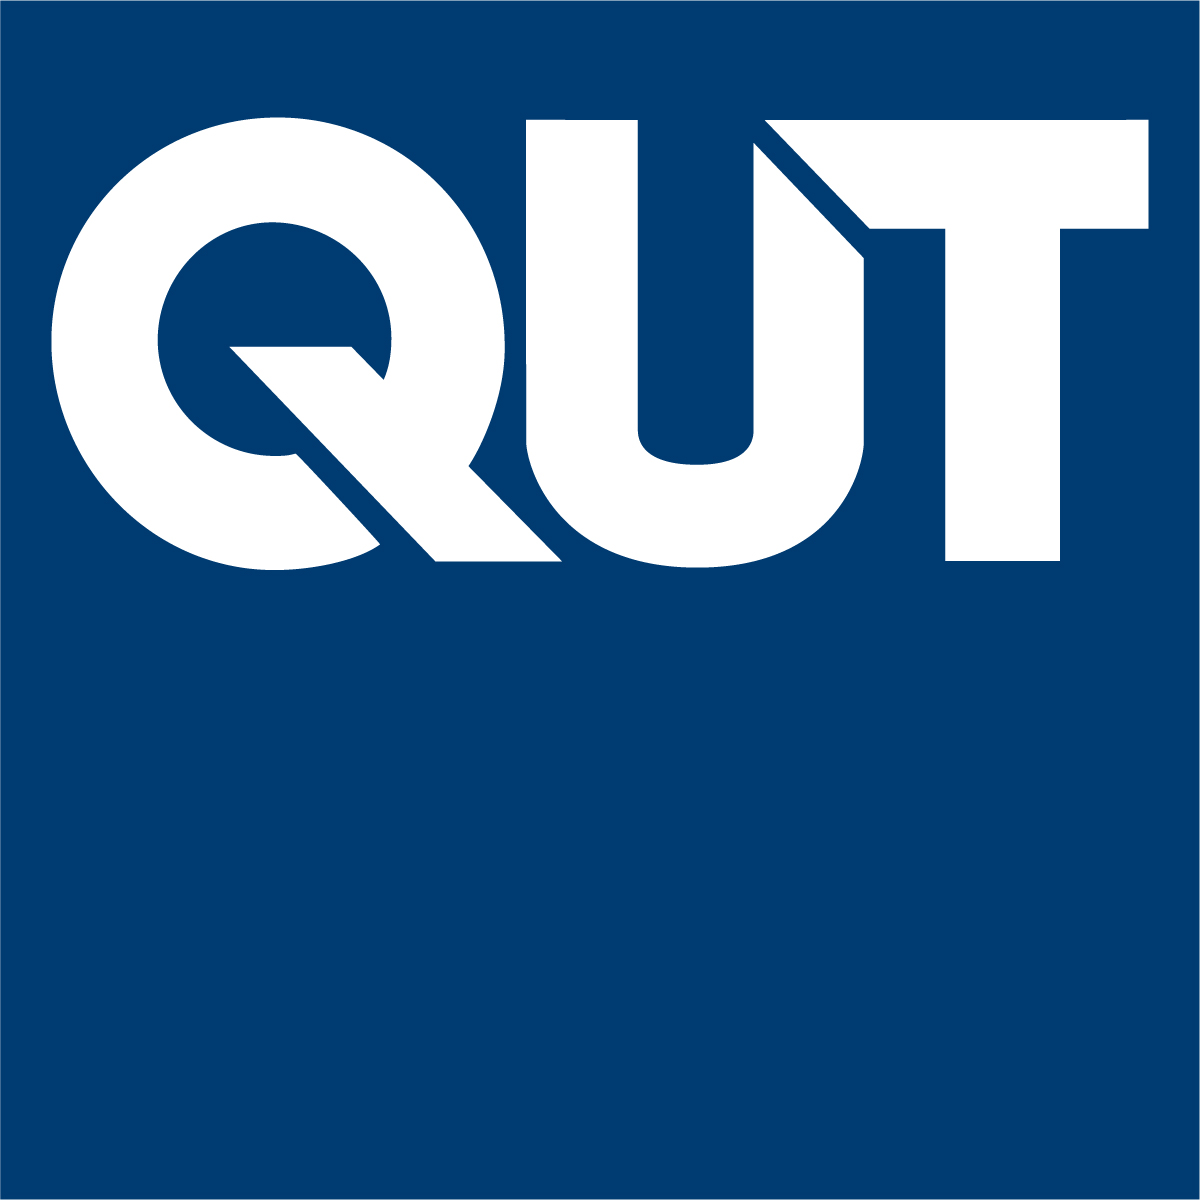

# MXB201 Linear Algebra in the Real World™ Series

Professor Tim Moroney,  2022

V1.0

## Scattered data interpolation and regularisation

Linear Algebra prerequisites:

- Vector norms

- Form and solve $Ax = b$ for square matrix $A$

Suppose we wish to find the minimum value of a function $f(x_1, x_2, \ldots, x_n)$ over some domain $\Omega$.  In vector notation, we want $\min_{x \,\in \,\Omega} f(x)$, where $\Omega \subset \mathbb{R}^n$.

If we know the formula for $f$, then this is a problem of continuous optimisation for which there are many algorithms, such as MATLAB's `fminsearch` (you can read about it in the documentation, but a discussion of how it works is outside the scope of this unit).  But what if instead all we know about $f$ are its values at some sampled input vectors $x \in \Omega$?  This is a common scenario in machine learning and elsewhere.  The components of the input vector $x$ represents values of all the parameters to the problem that we can control, and the output $f$ represents the "cost" associated with that combination of inputs.  We don't know the *formula* for this cost function, but for some particular inputs we have *measured* it.

The goal of the minimisation problem is to find what particular input vector achieves the minimum cost.  In some applications the dimension of the input vector can be hundreds, thousands, millions or even more.  But for today, we will consider a problem in only two dimensions.  That is, $x \in \Omega \subset \mathbb{R}^2$, and $\Omega$ will be the unit square.

We suppose that we have sampled the value of the function $f$ at the following set of input vectors -- let's call them points -- $x^{(i)}$ in the unit square, for $i = 1,\ldots,289$.  Note that we use the superscript notation $x^{(i)}$ to mean the $i$th input point.  These are stored in the provided `samples` workspace as the array `pts`.

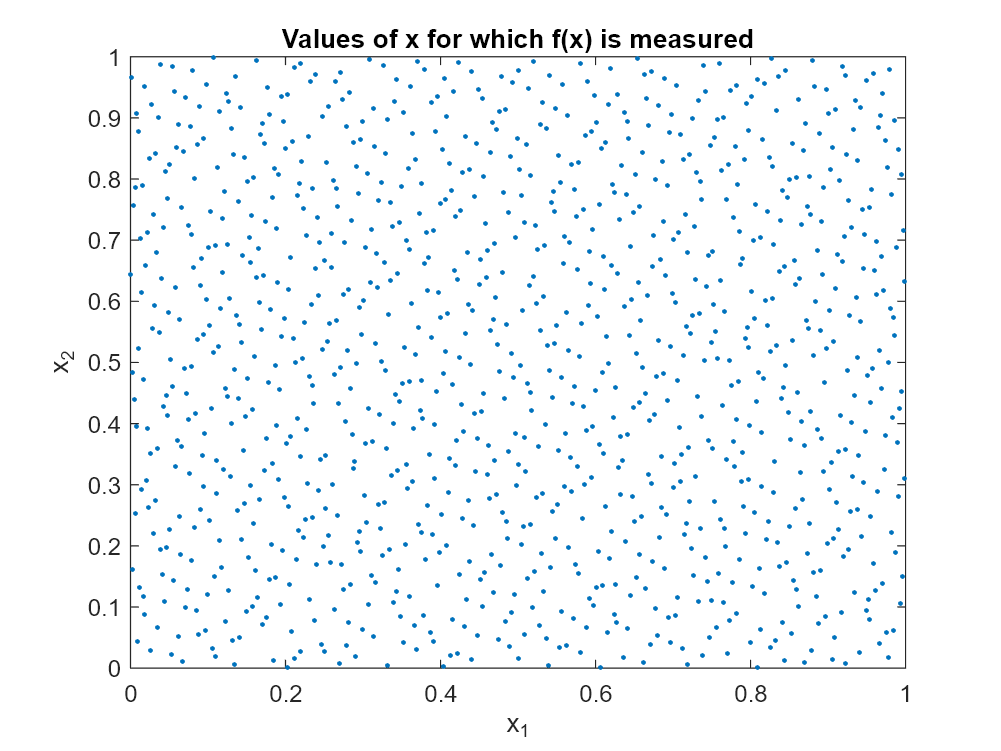

clear
load samples
figure
plot(pts(:,1), pts(:,2), '.')
xlabel x_1, ylabel x_2
title('Values of x for which f(x) is measured')

The corresponding measured function values $f_i = f(x^{(i)})$ are provided in the array `f`.

f

f =     0.9875
    1.5440
    0.9761
    1.1343
    1.6712
    0.9828
    1.2921
    1.2314
    0.9477
    1.1167


A crude visualisation of the function $f$ as a surface can be obtained by plotting the points and sampled values in three-dimensional space.

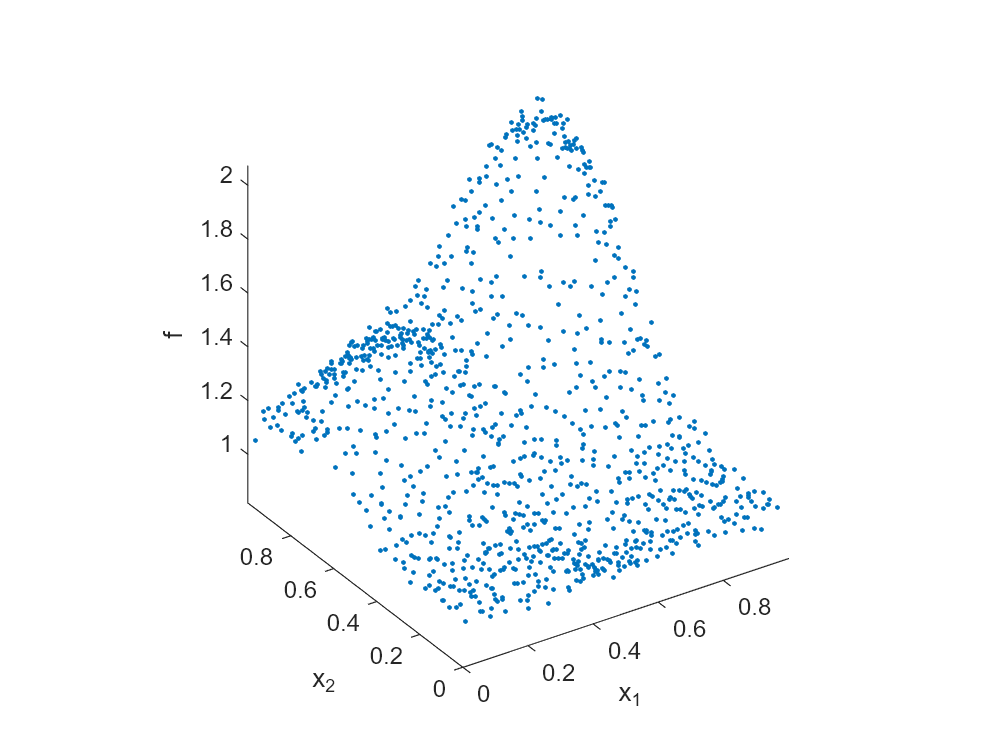

figure
plot3(pts(:,1), pts(:,2), f, '.')
axis vis3d
xlabel x_1, ylabel x_2
zlabel f

view([-33.46 30.34])

You might need to rotate this figure in 3D a bit to get a sense of what the surface looks like.

So currently we only know about $f$ through its measured values on a set of so-called "scattered data".   But we can use *interpolation* to turn this information into a continuous function that algorithms like `fminsearch `can deal with.  We will fit a continuous function $g$ through the data points.  But what type of function?  There are many choices, but today we will use a technique known as *radial basis functions*.

Let $x$ denote an arbitrary input to the function $g$, and we continue to refer to our sampled input points as $x^{(i)}$.  One option would be to compose the function $g$ as a linear combination of the *distances* from $x$ to each sample input $x^{(i)}$.


$$g(x) = \sum_{i=1}^n c_i\, \|x - x^{(i)}\|.$$


This is certainly a workable idea.  Each distance $\|x - x^{(i)}\|$ is a real number, and we combine these real numbers linearly to get the final output value $g(x)$.  The $n$ coefficients $c_i$ could be chosen to ensure that $g(x^{(i)}) = f(x^{(i)})$ for $i = 1\ldots n$.  That is, the coefficients would be chosen so that $g$ interpolates the known data.  In-between the known data, the function $g$ would fill in the gaps, so we'd have a continuous interpolant all throughout the unit square.

For more generality, we could even dream up a scalar function $\varphi : \mathbb{R}_{\geq 0} \to \mathbb{R}$ that maps nonnegative reals to reals, and feed the distances $\|x - x^{(i)}\|$ through this function before piecing them together.  That is, we define


$$g(x) = \sum_{i=1}^n c_i\, \varphi\big(\|x - x^{(i)}\|\big).$$


Notice that the function $\varphi$ operates only on the distance from $x$ to $x^{(i)}$, so it is an ordinary scalar function, known in the business as a **radial basis function (RBF)**.  Different choices of $\varphi$ give different smooth interpolants, all of which fit the data, but which in general disagree with one another elsewhere.

For today's problem, we will use the *thin plate spline* RBF

$\varphi(r) = r^2 \log(r)$,

which is a common choice in many applications, especially for two-dimensional input data like ours.  It's common, as we have done, to denote the input to $\varphi$ as $r$, since after all $\varphi$ will take as input the (radial) distances between points.

phi = @(r) r.^2 .* log(r);  % thin plate spline RBF

**Exercise**

Remember, we demand that $g(x^{(i)}) = f(x^{(i)})$ for $i = 1,\ldots n$.

By writing down the equations on paper, show that this amounts to the coefficient vector $\mathbf{c}$ satisfying the linear system:

$\left[\matrix{   \varphi\big(\|x^{(1)} - x^{(1)}\|\big) & \varphi\big(\|x^{(1)} - x^{(2)}\|\big)  &  \cdots & \varphi\big(\|x^{(1)} - x^{(n)}\|\big) \cr
\varphi\big(\|x^{(2)} - x^{(1)}\|\big) & \varphi\big(\|x^{(2)} - x^{(2)}\|\big)  &  \cdots & \varphi\big(\|x^{(2)} - x^{(n)}\|\big) \cr
\vdots & \vdots & \ddots & \vdots \cr
\varphi\big(\|x^{(n)} - x^{(1)}\|\big) & \varphi\big(\|x^{(n)} - x^{(2)}\|\big)  &  \cdots & \varphi\big(\|x^{(n)} - x^{(n)}\|\big)
 } \right]
\left[ \matrix{c_1 \cr c_2 \cr \vdots \cr c_n}\right] =
\left[ \matrix{f_1 \cr f_2 \cr \vdots \cr f_n}\right]$,

or compactly,

$A\textbf{c} = \textbf{f}$.

Why is this matrix $A$ is guaranteed to be symmetric?

Our goal must then be to *form* and *solve* this linear system to find the coefficients $c_i$.  Let's think of how we can form this matrix $A$ efficiently.  In fact, MATLAB provides a function to calculate pariwise distances for us, called `pdist2`.  So the matrix of pairwise distances from every point to every point is just

pdist2(pts, pts)

ans =          0    0.4167    0.3345    0.3911    0.4617    0.1672    0.4359    0.7071    0.3028    0.1911    0.4846    0.3632    0.2390    0.4855    0.4437    0.5357    0.5934    0.3392    0.2908    0.5331    0.2153    0.2076    0.6587    0.4079    0.3108    0.6487    0.4703    0.2815    0.4091    0.2122    0.4847    0.6658    0.1000    0.3316    0.6270    0.4580    0.1490    0.3980    0.4272    0.4514    0.5000    0.1826    0.4260    0.6739    0.3197    0.0983    0.6177    0.4730    0.2030    0.5684
    0.4167         0    0.7474    0.2550    0.3911    0.4617    0.6348    0.2908    0.7029    0.3028    0.5637    0.5223    0.4751    0.2390    0.7991    0.2310    0.3825    0.5934    0.5911    0.1195    0.6300    0.2153    0.6819    0.4020    0.3457    0.3108    0.8836    0.3225    0.4689    0.5856    0.7488    0.2649    0.5072    0.1000    0.5665    0.6269    0.4829    0.1490    0.8165    0.2438    0.3653    0.4027    0.5814    0.2756    0.7362    0.3197    0.7084    0.5112    0.3265   

We observe the symmetric nature of the matrix: each entry $(i,j)$ is just the distance from point $x^{(i)}$ to point $x^{(j)}$.  The diagonal entries are zero, because the distance from a point to itself is zero.

We just need to feed these distances through the $\varphi$ function to get our matrix $A$.

A = phi(pdist2(pts, pts))

A =        NaN   -0.1520   -0.1225   -0.1436   -0.1647   -0.0500   -0.1578   -0.1733   -0.1095   -0.0604   -0.1701   -0.1336   -0.0817   -0.1703   -0.1600   -0.1791   -0.1838   -0.1244   -0.1045   -0.1788   -0.0712   -0.0677   -0.1811   -0.1492   -0.1129   -0.1821   -0.1669   -0.1005   -0.1496   -0.0698   -0.1702   -0.1803   -0.0230   -0.1214   -0.1835   -0.1638   -0.0423   -0.1460   -0.1552   -0.1621   -0.1733   -0.0567   -0.1548   -0.1792   -0.1166   -0.0224   -0.1838   -0.1675   -0.0657   -0.1825
   -0.1520       NaN   -0.1626   -0.0888   -0.1436   -0.1647   -0.1831   -0.1044   -0.1742   -0.1095   -0.1822   -0.1772   -0.1680   -0.0817   -0.1432   -0.0782   -0.1406   -0.1838   -0.1837   -0.0303   -0.1834   -0.0712   -0.1780   -0.1473   -0.1270   -0.1129   -0.0966   -0.1177   -0.1665   -0.1835   -0.1622   -0.0932   -0.1746   -0.0230   -0.1824   -0.1835   -0.1698   -0.0423   -0.1352   -0.0839   -0.1344   -0.1475   -0.1833   -0.0979   -0.1660   -0.1166   -0.1730   -0.1754   -0.1193   -0

Oops!  The diagonal entries are coming out as `NaN`.

**Exercise**

Taking a closer look at our thin plate spline RBF $\varphi(r) = r^2\log(r)$, we notice it has an apparent singularity at $r = 0$.

On a piece of paper, show by taking the limit, that $r = 0$ is really just a removable singularity.

Hence, fix up the diagonal entries in the matrix $A$ accordingly.

% code to fix up the diagonal entries of A
for i = 1:length(A)
    A(i, i) = 0;
end

A

A =          0   -0.1520   -0.1225   -0.1436   -0.1647   -0.0500   -0.1578   -0.1733   -0.1095   -0.0604   -0.1701   -0.1336   -0.0817   -0.1703   -0.1600   -0.1791   -0.1838   -0.1244   -0.1045   -0.1788   -0.0712   -0.0677   -0.1811   -0.1492   -0.1129   -0.1821   -0.1669   -0.1005   -0.1496   -0.0698   -0.1702   -0.1803   -0.0230   -0.1214   -0.1835   -0.1638   -0.0423   -0.1460   -0.1552   -0.1621   -0.1733   -0.0567   -0.1548   -0.1792   -0.1166   -0.0224   -0.1838   -0.1675   -0.0657   -0.1825
   -0.1520         0   -0.1626   -0.0888   -0.1436   -0.1647   -0.1831   -0.1044   -0.1742   -0.1095   -0.1822   -0.1772   -0.1680   -0.0817   -0.1432   -0.0782   -0.1406   -0.1838   -0.1837   -0.0303   -0.1834   -0.0712   -0.1780   -0.1473   -0.1270   -0.1129   -0.0966   -0.1177   -0.1665   -0.1835   -0.1622   -0.0932   -0.1746   -0.0230   -0.1824   -0.1835   -0.1698   -0.0423   -0.1352   -0.0839   -0.1344   -0.1475   -0.1833   -0.0979   -0.1660   -0.1166   -0.1730   -0.1754   -0.1193   -0

Now it's time to solve for the coefficient vector $\mathbf{c}$.  That's just solving $A\textbf{c} = \textbf{f}$.

% We provide the solution in the array c_provided for your comparison.
% Replace this line with your own code to calculate c by solving Ac=f
c = A \ f

c =   116.4052
  -44.8037
  -28.4455
 -142.8448
   27.0325
   52.3201
  -54.0274
  118.6012
 -309.8399
  302.5475


norm(c - c_provided)

ans = 1.7030e-08

Our interpolating function $g$ is then calculated, for any input $x$ by $g(x) = \sum_{i=1}^n c_i\, \varphi\big(\|x - x^{(i)}\|\big)$.

g = @(x) phi(pdist2(x, pts)) * c;  % this is a row vector times a column vector

Now for the grand reveal!  Let's plot the function $g$ and see how it looks.  We expect it to be a continuous surface that "fills in the gaps" in our earlier dot plot.

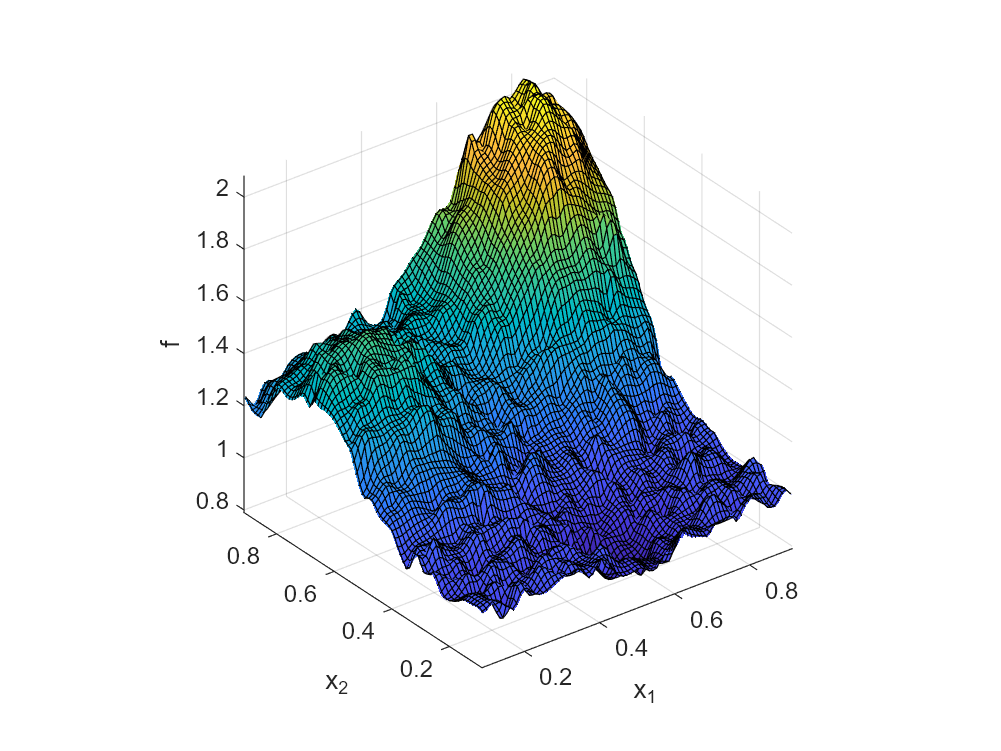

gridsize = 100;
[X1, X2] = meshgrid(linspace(0,1,gridsize));
G = g([X1(:) X2(:)]);
G = reshape(G, size(X1));
figure
surf(X1, X2, G)
axis vis3d
xlabel x_1, ylabel x_2
zlabel f

xlim([0.087 0.913])
ylim([0.087 0.913])
zlim([0.79 2.08])

Well it's certainly a bumpy old surface!

But remember, where did the data values $f_i$ come from in the first place?  Answer: they were *measured*.

Hence, a likely explanation for what we're seeing is that the data we've been provided with are contaminated with a certain amount of *noise*.  So, when we fit an interpolating function through those data, it necessarily comes out bumpy and wiggly, because it's actually fitting to the noise.

Now, this isn't just a cosmetic concern.  It causes real problems if we try to minimise the function using an optimiser like `fminsearch`, because the algorithm is almost certain to get stuck in one of the many local minima.

For example, if we try `fminsearch`, with starting point $[0.5, 0.5]$, we find

minloc = fminsearch(g, [0.5,0.5])

minloc =     0.5103    0.4703


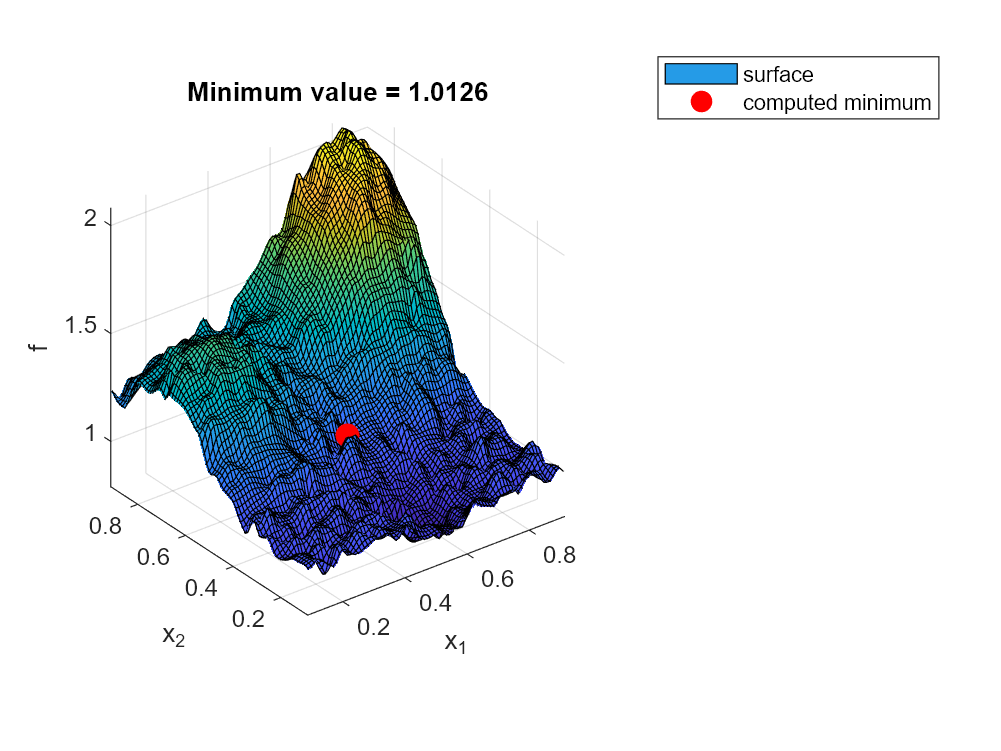

hold on
plot3(minloc(1), minloc(2), g(minloc)+0.1, 'r.', 'markersize', 30)
legend("surface", "computed minimum")
title("Minimum value = " + num2str(g(minloc)))

Rotate the figure and you can clearly see that the computed minimum is far from the true minimum of the function.  If you think of `fminsearch` as "rolling a red ball downhill" (it's smarter than that in reality, but the analogy will suffice), we see that the red ball just got stuck in a little hole on the way, and couldn't get out again.

The problem is perhaps even clearer if we look down at our surface from above.  Here's a contour plot, showing the the large number of local minima, one of which `fminsearch` has managed to get stuck in (not surprisingly right near its starting point $[0.5, 0.5]$).

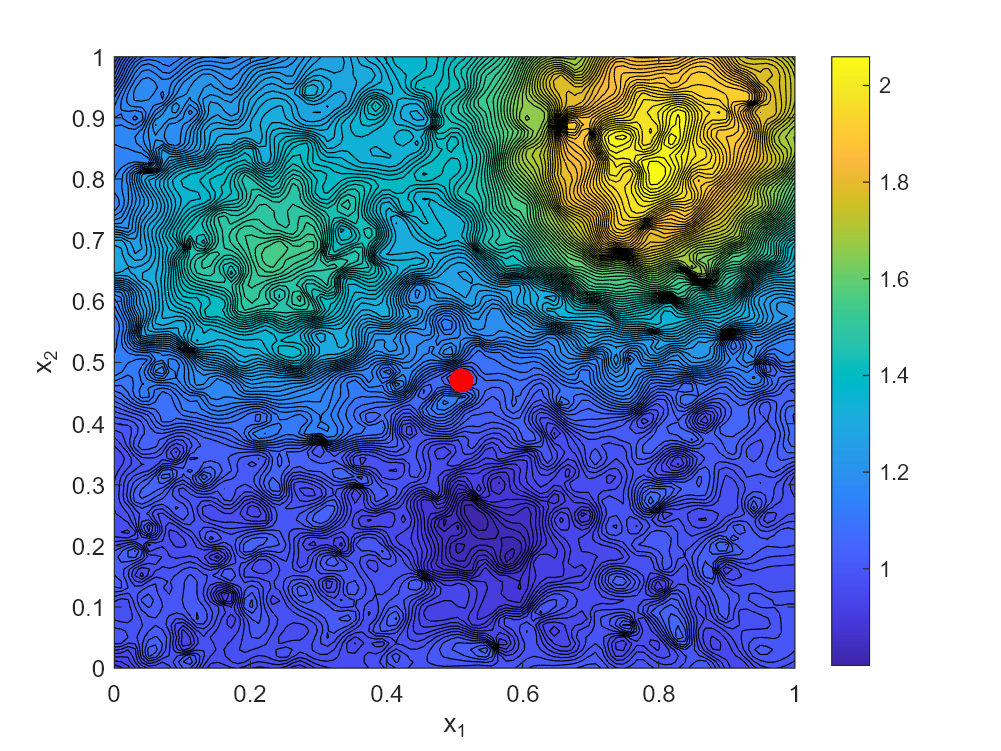

figure
contourf(X1, X2, G, 100)
xlabel x_1, ylabel x_2
hold on
plot(minloc(1), minloc(2), 'r.', 'markersize', 30)
colorbar

This kind of problem arises all the time in the Real World™, because it's almost inevitable that any measured data will be contaminated with some level of noise.

Notice that we might have suspected something was the matter by observing the values of the coefficient vector $\textbf{c}$:

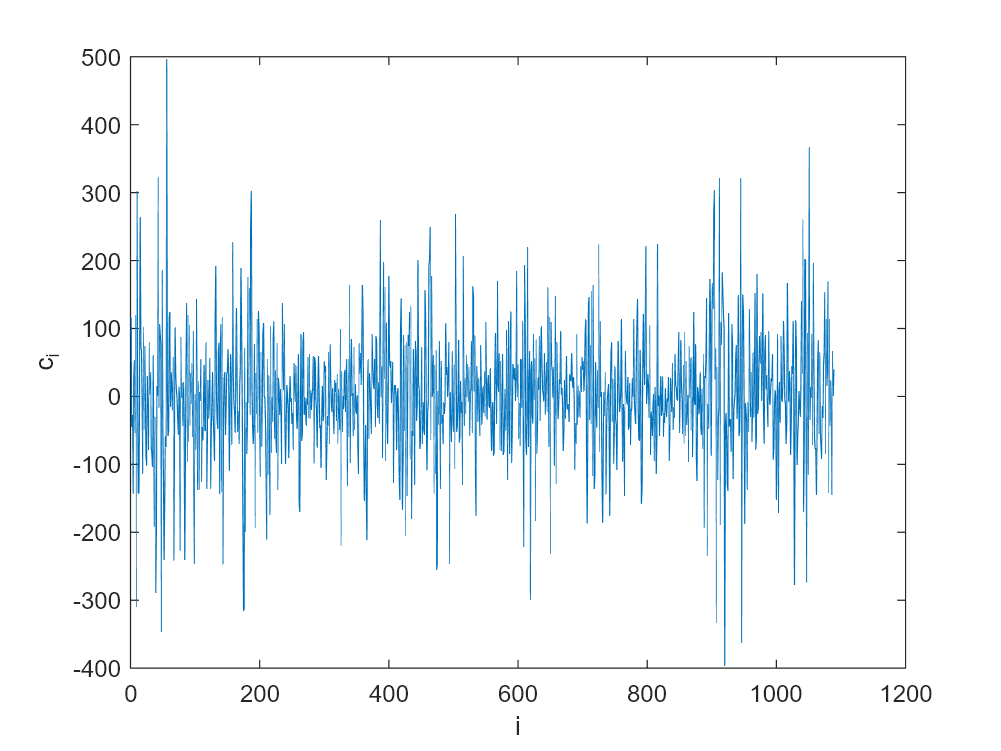

figure
plot(c)
xlabel i, ylabel c_i

From the surface plot we saw that the sample function values (the $f_i$) are all roughly between one and two.  But these coefficients $c_i$ are bouncing around across a range spanning three orders of magnitude as they try to wrestle our smooth basis functions into a linear combination that reconstructs what turn out to be decidedly *non-smooth* data.

The solution to our problem is to relax the requirement that the function $g$ *exactly* interpolates the measured data.  Instead, we will require only that $g$ *approximately *interpolates the data, while also imposing the constraint that it doesn't "wiggle too much".

The measure by which $g$ fails to interpolate the data is the norm $\|\textbf{f} - A\textbf{c}\|$.  Meanwhile, based on our observation of the coefficient vector $\textbf{c}$ above, a sensible measure of "wiggliness" would appear to be the norm of that vector, $\|\textbf{c}\|$: a small norm corresponds to a "smoother" interpolant, while a larger norm (like we had above, with many large positive and negative entries) corresponds to a bumpy or "wiggly" interpolant.  So, ideally we would like to minimise some combination of these two factors:


$$\|\textbf{f} - A\textbf{c}\|^2 + \rho \|\textbf{c}\|^2$$


( = interpolation error + wiggliness penalty )

where $\rho$ is a so-called *regularisation parameter *that we can tune to adjust the trade-off between fitting the data exactly (small $\rho$) and keeping the wiggliness down (large $\rho$).  Note that we're actually proposing to use squared norms in our minimisation to make the calculations easier.

Now it happens that the maths works out nicer if instead of $\|\textbf{c}\|^2$ we use $\textbf{c}^T A \textbf{c}$ as the measure of wiggliness.  Notice that these aren't the same thing: $\|\textbf{c}\|^2$ is $\textbf{c}^T \textbf{c}$, while we're now proposing instead to use $\textbf{c}^T A \textbf{c}$.  But even so, it still supports our goal of removing excessive wiggling: penalising large values of $\textbf{c}^T A \textbf{c}$ will still mean smoothness is favoured over wiggliness.

So, happy with our plan, we will find our coefficient vector $\mathbf{c} \in \mathbb{R}^n$ by minimising the following expression with respect to $\mathbf{c}$:


$$(\mathbf{f}-A\mathbf{c})^T(\mathbf{f}-A\mathbf{c}) + \rho\, \mathbf{c}^TA\mathbf{c}$$


( = interpolation error + modified wiggliness penalty )

**Exercise**

To minimise this expression, calculus tells us that we should differentiate with respect to $\mathbf{c}$, and solve for the derivative equal to zero.

- Differentiate the expression above with respect to $\mathbf{c}$.  Now this isn't a class on matrix calculus, so feel free to jump over to our good friends at [http://www.matrixcalculus.org/](http://www.matrixcalculus.org/) and let them do the work for you.

- Take your expression for the derivative, set it equal to zero, and rearrange to solve for $\mathbf{c}$.

You should obtain a new linear system, one that generalises $A\textbf{c} = \textbf{f}$ by including the impact of the regularisation parameter $\rho$.

rho = 0.05;
N = size(pts, 1);
c_smooth = (A * (rho * eye(N) + A)) \ (A * f)

c_smooth =     0.6920
    0.3719
   -0.3103
   -0.3648
   -0.1878
    0.0828
   -0.0240
    0.5301
   -0.7428
    0.7359


g_smooth = @(x) phi(pdist2(x, pts)) * c_smooth;  % this is a row vector times a column vector

Now for the grand reveal!  Let's plot the function $g$ and see how it looks.  We expect it to be a continuous surface that "fills in the gaps" in our earlier dot plot.

gridsize = 101;
[X1, X2] = meshgrid(linspace(0,1,gridsize));
G = g_smooth([X1(:) X2(:)]);
G = reshape(G, size(X1));
figure
surf(X1, X2, G)
axis vis3d
xlabel x_1, ylabel x_2
zlabel f

xlim([0.087 0.913])
ylim([0.087 0.913])
zlim([0.79 2.08])

minloc = fminsearch(g_smooth, [0.5,0.5])

minloc =     0.5476    0.2176


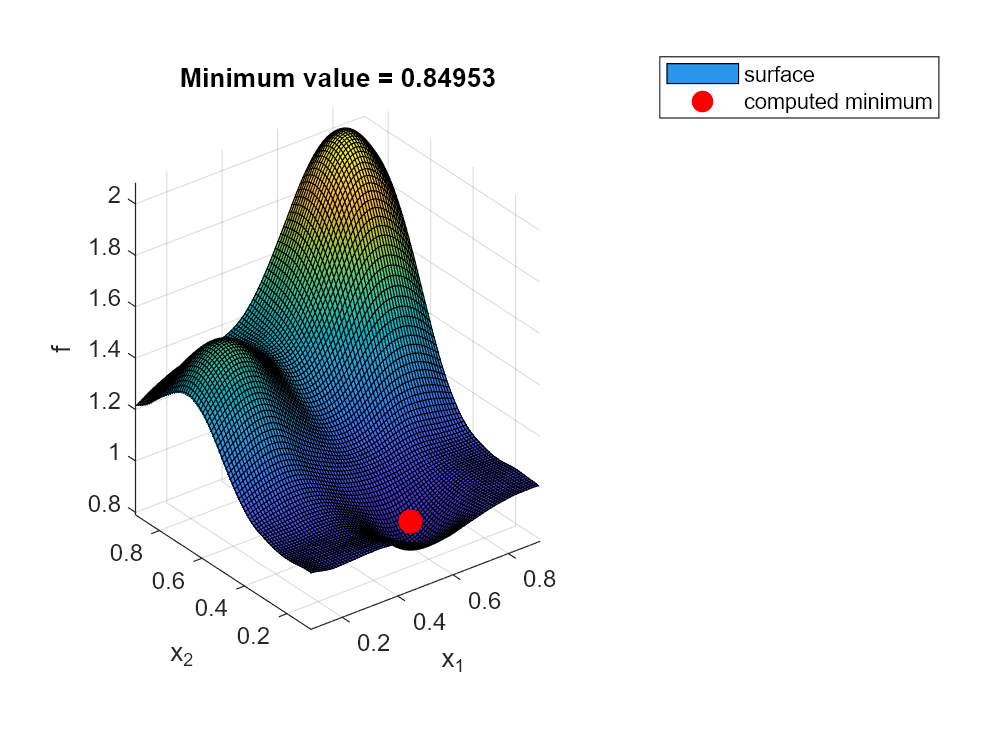

hold on
plot3(minloc(1), minloc(2), g_smooth(minloc)+0.1, 'r.', 'markersize', 30)
legend("surface", "computed minimum")
title("Minimum value = " + num2str(g_smooth(minloc)))

Now go back and update your linear system solve to use this new regularised equation.  You will need to choose an appropriate value of $\rho$ by trial and error.  Not imposing any penalty for wiggliness corresponds to setting $\rho=0$, so that should recover your original surface.  Then, you can gradually wind up the value of $\rho$ to find a suitable compromise between interpolation error and wiggliness.  But be warned that if you wind up the value of $\rho$ *too far*, you'll get an overly-smoothed surface that no longer captures the real features of the data.

With any luck, you should be able to produce a figure something like the one shown below.  No great effort has been made in fine-tuning the parameter $\rho$ for this figure, so don't aim to reproduce it exactly.

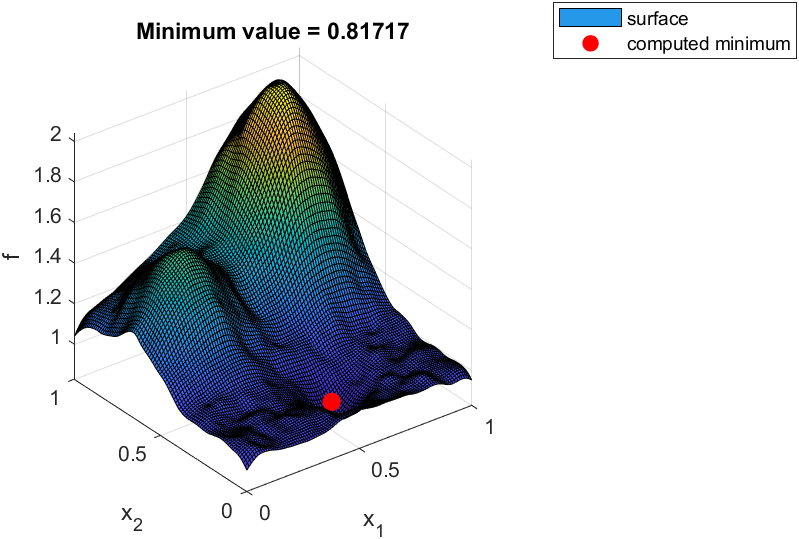

Notice how the optimiser has no trouble finding the true local minimum now that the myriad spurious local minima we had before are gone.

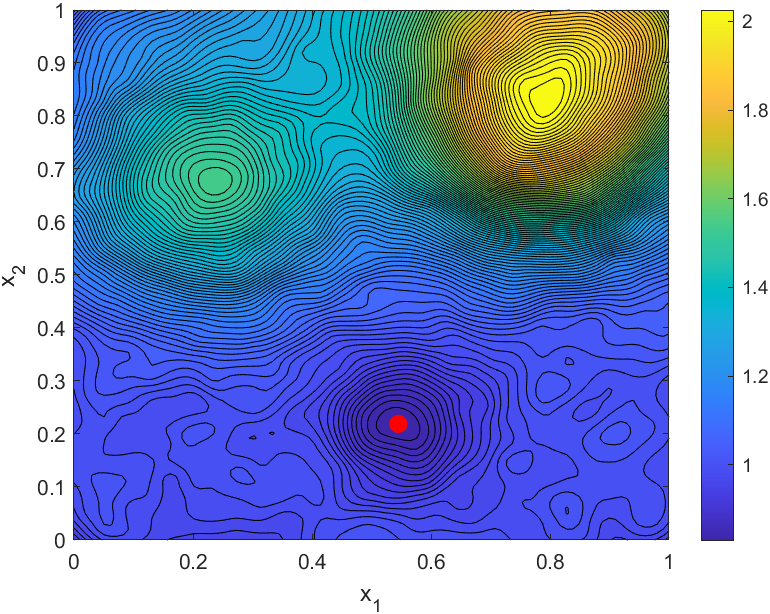

Incidentally, you might observe that the surface above appears to go even lower around the edges of the domain than at this local minimum.  Perhaps we should be checking the boundary values for the true minimum of $g$?  Don't be misled.  Radial basis function interpolants are much less accurate near the boundaries of the data, compared to the interior.  You shouldn't trust the trend of this surface near the boundaries.  This is really no different from any other form of interpolation: if you're sampling at the edge or (especially) beyond the range of your data, you should be very wary of reading too much into the results.

So there you have it.  You've learned how to regularise a problem of scattered data fitting, to reduce its sensitivity to noise.  This idea crops up quite often across applied mathematics and statistics.  Applied mathematicians tend to call this type of thing *Tikhonov regularisation*, while in statistics it goes by the name *ridge regression*.

Please feel free to [provide feedback on this week's practical activity](https://forms.office.com/Pages/ResponsePage.aspx?id=o1IL3MVo90SIHZOD2IULlippL5Tej5JHuWnaChxNwu9UQTVXTlBURjg3SFdIQlpERVcyQzNaU0JSQS4u) by clicking the link to an online form.  Feedback is anonymous, and comprises just three questions rating the interest, difficulty and length of the activity.

**References**

Adapted from 

- `TPS_RidgeRegression2d` in Gregory E. Fasshauer, *Meshfree Approximation Methods with MATLAB*, 2007.

**Further reading**

More on radial basis functions.

- Martin Buhmann (2010) [Radial basis function](http://www.scholarpedia.org/article/Radial_basis_function). Scholarpedia, 5(5):9837.

Here's the idea in action applied to reconstructing leaf surfaces from noisy scans.

- Whebell, Riley M., Timothy J. Moroney, Ian W. Turner, Ravindra Pethiyagoda, and Scott W. McCue. “Implicit Reconstructions of Thin Leaf Surfaces from Large, Noisy Point Clouds.” *Applied Mathematical Modelling* 98 (October 1, 2021): 416–34. [https://doi.org/10.1016/j.apm.2021.05.014](https://doi.org/10.1016/j.apm.2021.05.014).